# Derivative of state '1' in block 'X/Y/Integrator' at time 0.55 is not finite

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2024_05_15_InfiniteDerivative/2024_05_15_InfiniteDerivative.prj)

Let's look at another frequently visited [MATLAB Answers](https://www.mathworks.com/matlabcentral/answers/help) page:

[Derivative of state '1' in block 'X/Y/Integrator' at time 0.55 is not finite.](https://www.mathworks.com/matlabcentral/answers/252574-derivative-of-state-1-in-block-x-y-integrator-at-time-0-55-is-not-finite)

## The Problem

Here is a simple model similar to the one I have been using recently in multiple posts.

mdl = "suspension";
open_system(mdl);

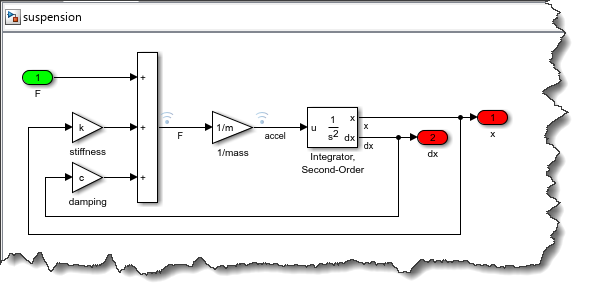

When simulating the model, we get the same error as reported in MATLAB Answers:

in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('Stoptime','500');
in = in.setModelParameter('CaptureErrors','on');
out= sim(in);
out.ErrorMessage

ans = 'Derivative of state 'dx' in block 'suspension/Integrator, Second-Order' at time 284.04767405115081 is not finite. The simulation will be stopped. There may be a singularity in the solution.  If not, try reducing the step size (either by reducing the fixed step size or by tightening the error tolerances)'

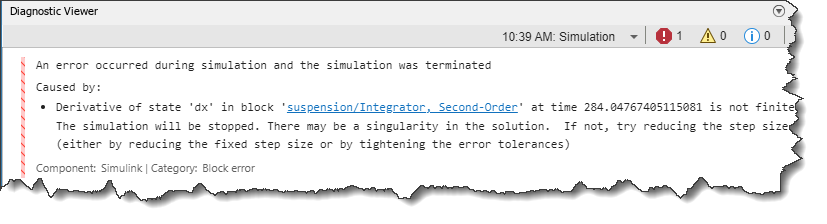

This error can be triggered by multiple reasons. Before diving into the reasons, I would like to highlight the tools that are the most likely to help you diagnose this type of issue.

## Debugging Tools

#### Solver Profiler

Try simulating using the [Solver Profiler](https://www.mathworks.com/help/releases/R2024a/simulink/slref/solverprofiler.html), which you can launch from the Debug tab:

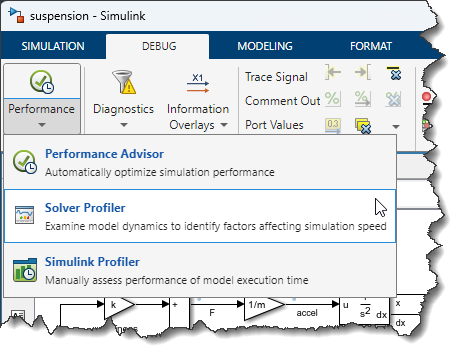

In the Explore Gallery, launch the States Explorer.

This will allow you to quickly scan all the states in the model and identify which states are diverging:

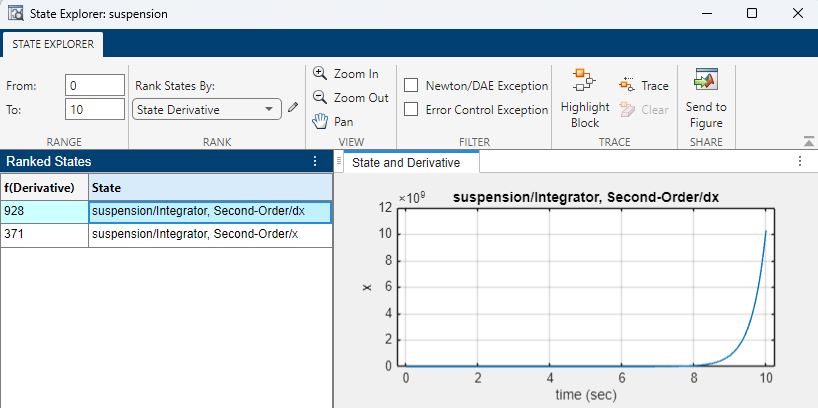

#### Highlight Source

Another useful tool is to [Highlight Signal to Source](https://www.mathworks.com/help/releases/R2024a/simulink/ug/displaying-signal-sources-and-destinations.html) the signal entering the block reported in the error message:

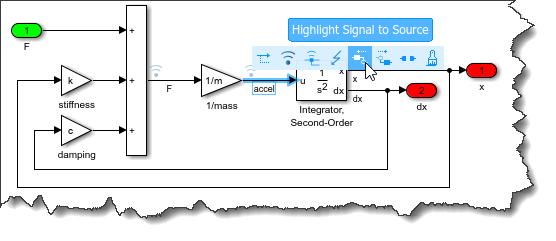

Once enabled, use the arrow keys to highlight the upstream blocks feeding the integrator and try understanding the logic making the equations unstable.

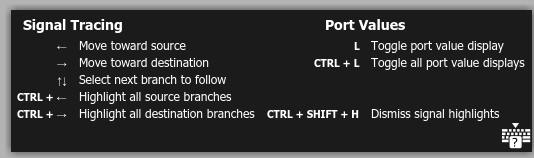

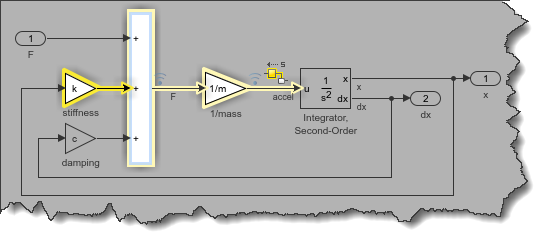

#### Simulink Debugger

The [Simulink Debugger](https://www.mathworks.com/help/releases/R2024a/simulink/simulation-stepper.html) allows you to step block by block during a simulation, which can be useful to diagnose this kind of issue.

First, select the blocks upstream of the block listed in the error message and enable [Port Value Display](https://www.mathworks.com/help/releases/R2024a/simulink/ug/displaying-block-outputs.html).

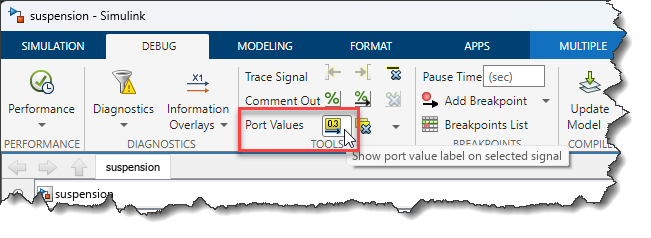

Select the signal entering the problematic block and add a breakpoint. You have the option to break on `Inf or NaN`, but I recommend breaking earlier to better observe what happens before the error. 

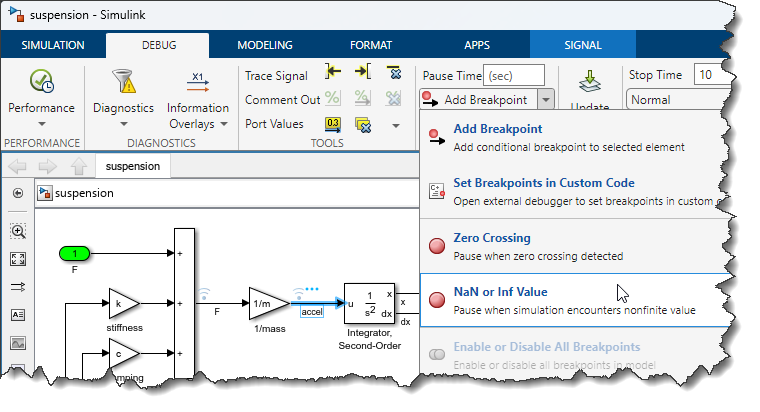

Click Run and when the breakpoint is hit, you will be able to step block by block to try identifying the problem with the equations in your model.

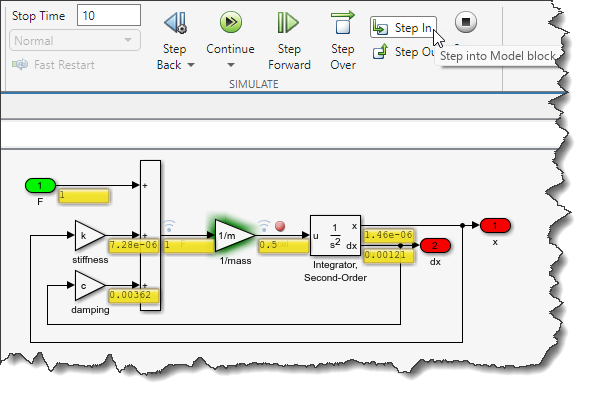

Let's now look at the most common situations leading to this error.

## Reason 1: Unstable System

The most common reason for this error is that equations in the model are unstable. This usually happens if the algorithm has been implemented incorrectly, or if you are simulating a system that is truly unstable. 

It can be useful to plot the state mentioned in the error message to see that it diverges toward infinity:

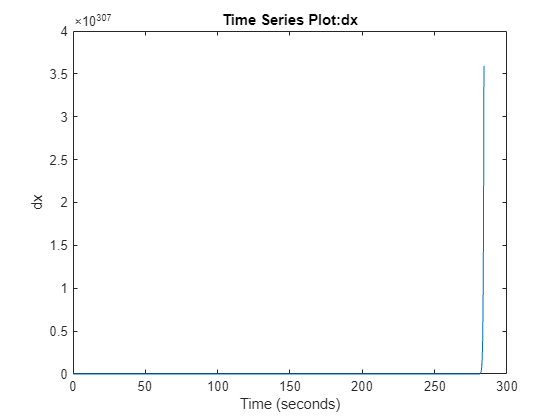

plot(out.xout.get('dx').Values)

In this simulation, the size of the model makes it easy to identify the problem. Here is an animation where I enabled port value display for all blocks and I am slowly stepping the model forward so we can see the evolution of each signal. Notice how the values are increasing at each time step:

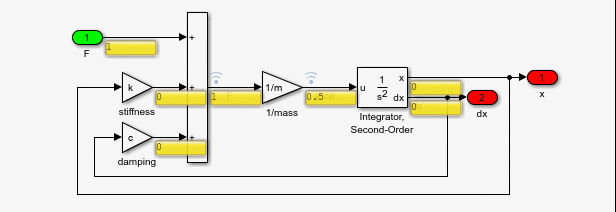

The implementation mistake here is that signs specified in the Sum block result in a positive feedback loop. To solve the problem and make this simulation behave as the mass-spring-damper it is trying to model, we need to make the signs of the feedback signals entering the Sum block negative.

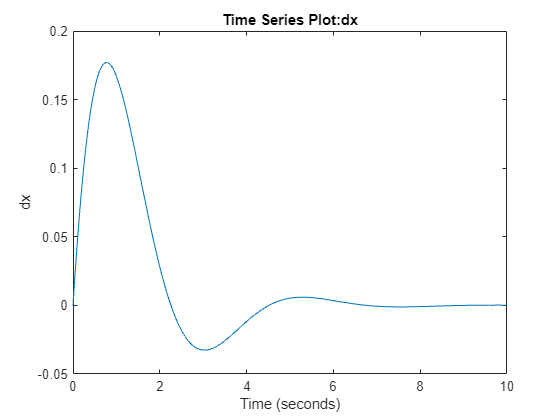

in = Simulink.SimulationInput(mdl);
in = in.setBlockParameter('suspension/Sum','Inputs','+--');
out = sim(in);
plot(out.xout.get('dx').Values)

## Reason 2: Step size is too large

As described in the error message, one possible reason for this error is the solver taking too large steps. This typically happens when using fixed-step solver, which is necessary to generate code and deploy to real-time systems.

Here is a slightly different version of the model.

mdl = "suspensionFixedStep";
open_system(mdl);

I fixed the signs of the Sum block to make the equations stable, but I changed the solver to `ode3` with a step size of 1 second.

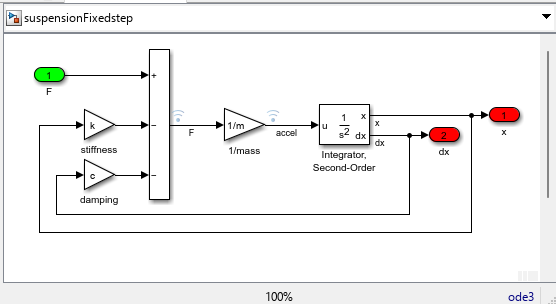

I will simulate the model with larger values for `k `and` c`, making the system dynamic fast and impossible to capture properly with the step sized of 1 seconds.

in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('CaptureErrors','on');
in = in.setVariable('k',1e5);
in = in.setVariable('c',100);
out = sim(in);
out.ErrorMessage

ans = 'Derivative of state 'dx' in block 'suspensionFixedStep/Integrator, Second-Order' at time 49.5 is not finite. The simulation will be stopped. There may be a singularity in the solution.  If not, try reducing the step size (either by reducing the fixed step size or by tightening the error tolerances)'

There are multiple ways to analyze the system and decide how to deal with this error.

#### Analysis 1: The Equations

A first approach is to analyze the equations in the model. This is obviously easier if the model is small. In this example, we have a [mass-spring-damper system](https://en.wikipedia.org/wiki/Mass-spring-damper_model). The natural frequency of this system can be computed analytically using:

omega_n = sqrt(k/m)

omega_n = 223.6068

This means that the system will oscillate with a period of:

T = 2*pi/omega_n % oscillation period in seconds

T = 0.0281

To capture this oscillation accurately, we need at least a minimum number of points per oscillation. 

#### Analysis 2: Linearization

Another approach to study the dynamics of the equations in your system is to linearize it using [Simulink Control Design](https://www.mathworks.com/products/simcontrol.html).

linsys = linearize(mdl);

We can then extract the natural frequency using [damp](https://www.mathworks.com/help/releases/R2024a/control/ref/dynamicsystem.damp.html). Thanks to [MATLAB GPT](https://chatgpt.com/g/g-QFTjbeK3U-matlab) for [reminding me the existence of damp](https://chatgpt.com/share/4e0e9c9e-ce4c-49da-86d3-4dd0053be406).

[wn, zeta, p] = damp(linsys);
T_lin = 2*pi/max(wn) % oscillation period in seconds

T_lin = 0.0281

#### Analysis 3: Variable-Step Solver

When getting this error with a fixed-step solver, one option is simulating the model with a variable-step solver. First, this gives you a good reference in terms of accuracy.

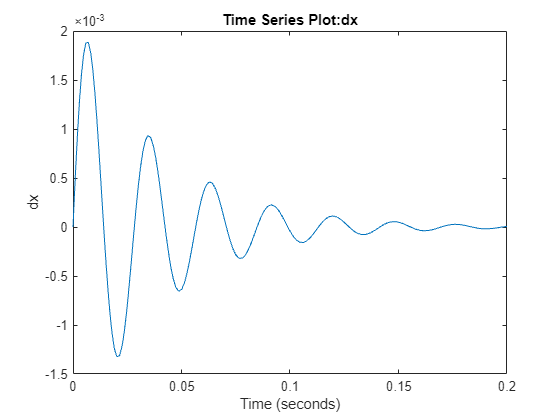

in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('SolverType','Variable-step');
in = in.setModelParameter('StopTime','0.2');
in = in.setVariable('k',1e5);
in = in.setVariable('c',100);
outVarStep = sim(in);
figure
plot(outVarStep.xout.get('dx').Values);

Second, seeing what time steps the variable-step solver is taking can be useful to pick a fixed step-size. The [Solver Profiler](https://www.mathworks.com/help/releases/R2024a/simulink/slref/solverprofiler.html) has a Step Size plot that can help with that. In this case, we can see that the variable-step solver needs to take steps slightly smaller than 0.01 second. 

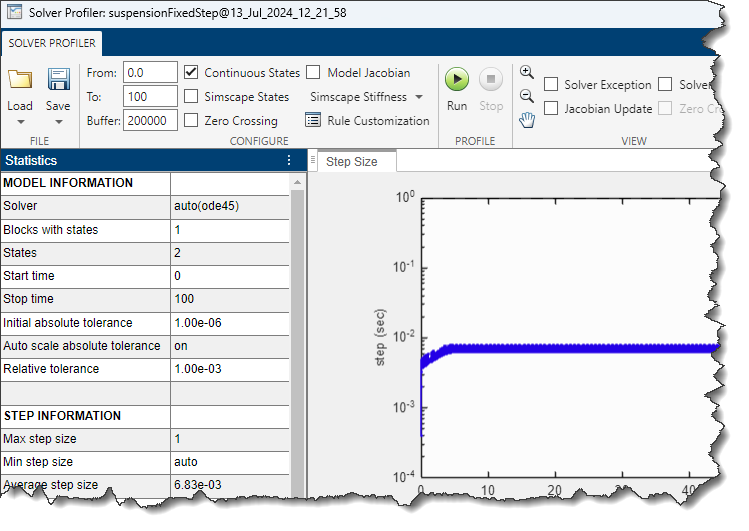

Once you better understand the system dynamic, it's time to look into solutions.

#### Solution 1: Smaller step-size

Let's try simulating the model with different fixed-step size and see what the results look like.

ts = [0.0005 0.001 0.002 0.005 0.01];
clear in
in(1:length(ts)) = Simulink.SimulationInput(mdl);
for i = 1:length(ts)
    in(i) = in(i).setModelParameter('FixedStep',num2str(ts(i)));
    in(i) = in(i).setModelParameter('StopTime','0.2');
    in(i) = in(i).setVariable('k',1e5);
    in(i) = in(i).setVariable('c',100);
end
out = sim(in,'ShowProgress','off');

Looking at the results, we can see that they become less and less accurate as the step size increase. If simulated for a larger stop time, the last step size of 0.01 would eventually error out with the infinite derivative error.

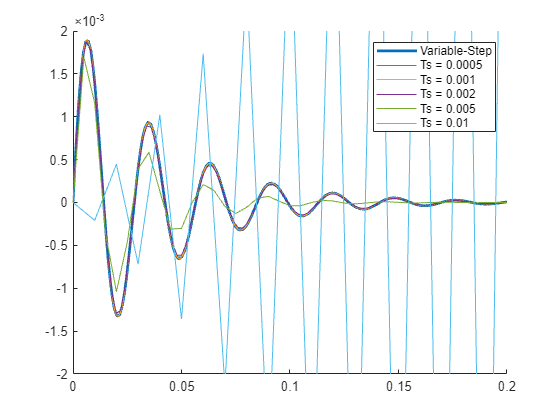

figure;hold on
plot(outVarStep.xout.get('dx').Values,'linewidth',2);
for i = 1:length(ts)
    plot(out(i).xout.get('dx').Values)
    legendLabel{i} = ['Ts = ' num2str(ts(i))]; %#ok<SAGROW>
end
axis([0 0.2 -2e-3 2e-3])
legend([ 'Variable-Step' legendLabel]);

#### Solution 2: Use a different solver

The solver being used can also impact the accuracy of the results. The higher the order, the more computationally expensive, but also the more accurate a solver is.

solvers = {'ode1','ode3','ode5','ode1be'};
clear in
in(1:length(solvers)) = Simulink.SimulationInput(mdl);
for i = 1:length(solvers)
    in(i) = in(i).setModelParameter('FixedStep','0.005');
    in(i) = in(i).setModelParameter('StopTime','0.5');
    in(i) = in(i).setModelParameter('Solver',solvers{i});
    in(i) = in(i).setVariable('k',1e5);
    in(i) = in(i).setVariable('c',100);
end
out = sim(in,'ShowProgress','off');

Here we can see that `ode1` is unstable while `ode5` gives results close to the variable-step solver. `Ode1be` is an [implicit solver](https://www.mathworks.com/help/releases/R2024a/simulink/ug/compare-solvers.html#bsfsnf4) that is especially good at remaining stable when solving stiff systems.

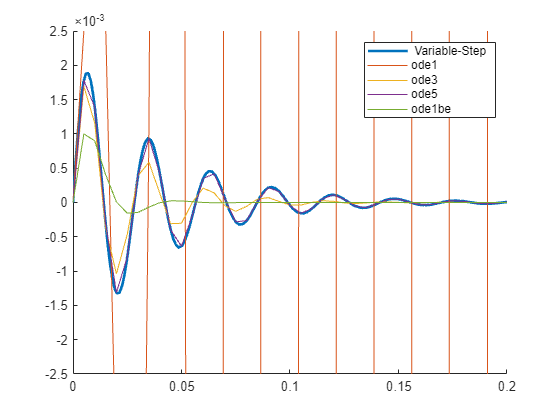

figure;hold on
plot(outVarStep.xout.get('dx').Values,'linewidth',2);
for i = 1:length(solvers)
plot(out(i).xout.get('dx').Values)
end
axis([0 0.2 -2.5e-3 2.5e-3])
legend([' Variable-Step' solvers]);

#### Solution 3: Modify the system dynamics

In some cases, real-time constraints can make it impossible to use a larger step-size or a more accurate solver. In such case, the solution is most likely to try simplifying the system equations or to soften the dynamics. 

The Simscape documentation has an extensive section on techniques to adapt a model for real-time simulation: [Real-Time Simulation](https://www.mathworks.com/help/releases/R2024a/simscape/real-time-simulation.html). Many of those techniques are not Simscape-specific and also apply to any Simulink model.

## Division by Zero

This one might sound obvious, but if the equations in the model return `Inf` and this `Inf` is passed to an Integrator block, you will get this error. One common reason for that is a [division by zero](https://en.wikipedia.org/wiki/Division_by_zero).

mdl = "example3";
open_system(mdl);
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('CaptureErrors','on');
out = sim(in);
out.ErrorMessage

ans = 'Derivative of state '1' in block 'example3/Integrator' at time 0.89047195013357083 is not finite. The simulation will be stopped. There may be a singularity in the solution.  If not, try reducing the step size (either by reducing the fixed step size or by tightening the error tolerances)'

To diagnose this, I recommend using the Simulink Debugger. Setting a breakpoint on `Inf` or `NaN` will stop the simulation at the first block where the Inf is generated.

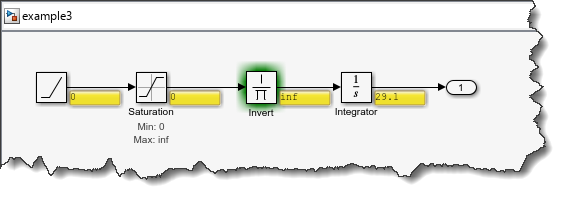

In this case, the solution is to modify the equations to avoid feeding `Inf` to Integrator blocks.

## Now it's your turn

Have you run into problems with infinite derivative error? Let us know in the comments below.